### Visualise cleaned signals

NB!! First run "Filter.mlx" to generate regioned data

regioned_file_dir = "../physionet.org/regioned_data/";

fileList = dir(regioned_file_dir+"*.txt") %only consider all text files

fileList = 68×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


xLim1 = 5370

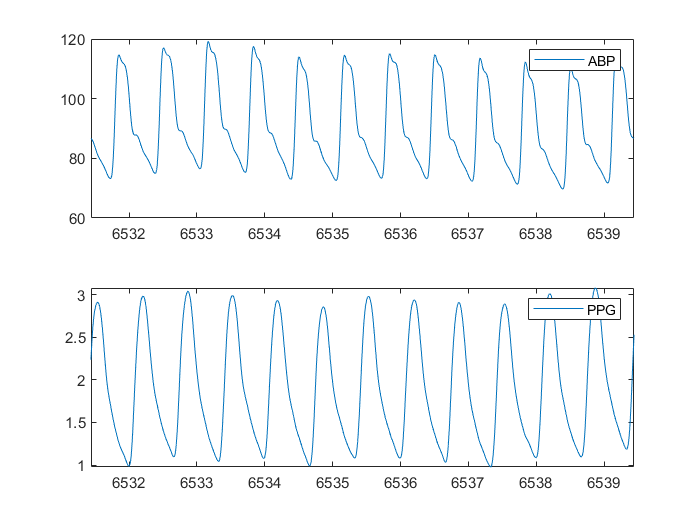

xLim1 = 3190

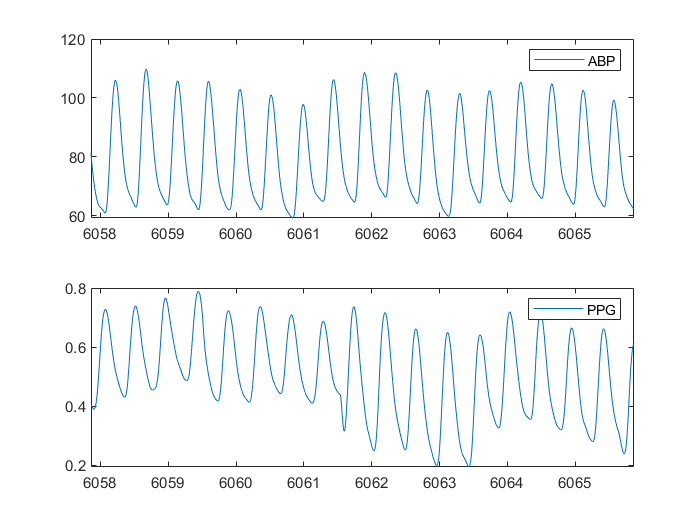

xLim1 = 3412

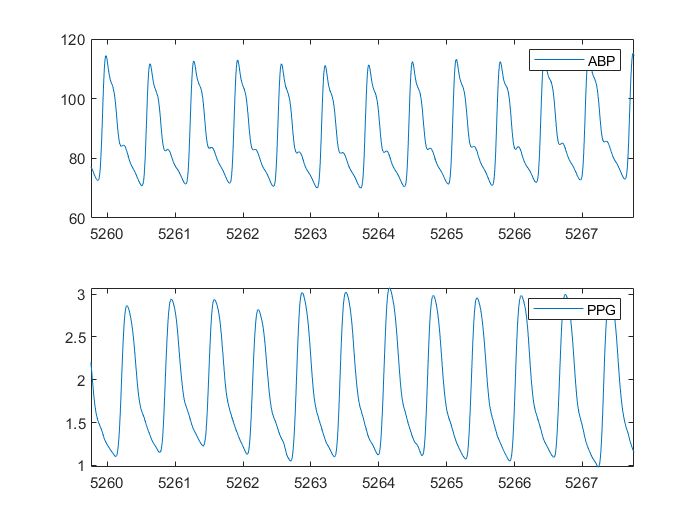

xLim1 = 6860

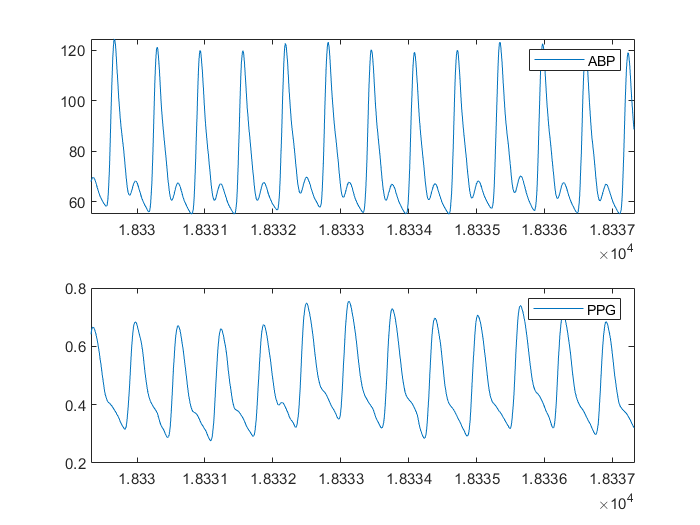


numPlots = 4;

plotId = randperm(length(fileList), numPlots);

for idx = 1:numPlots
    dataFile = fopen(regioned_file_dir + fileList(plotId(idx)).name);
    data = cell2mat(textscan( dataFile,'%f %f %f'));
    fclose(dataFile);
    
    xLim1 = randi(length(data) - 2000, [1 1])
    figure;
    subplot(2,1,1)
    plot(data(:,1), data(:,2));
    legend(["ABP"])
    xlim([data(xLim1,1) data(xLim1+1000,1)])
    
    subplot(2,1,2)
    plot(data(:,1), data(:,3));
    legend(["PPG"])
    xlim([data(xLim1,1) data(xLim1+1000,1)])
    
end

Segment all signals

allData = cell(length(fileList), 1);

segmentedData = {}


segmentedData =

  0×0 empty cell array



numPeriodsPerSegment = 20

numPeriodsPerSegment = 20


% Read in all data and apply segmentation function
% Concatenate all cell data
parfor id = 1:length(fileList)
    dataFile = fopen(regioned_file_dir + fileList(id).name);
    allData{id} = cell2mat(textscan( dataFile,'%f %f %f'));
    fclose(dataFile);
    
    segmentedFileData = segmentSignal(allData{id}, numPeriodsPerSegment, 3);
    % Reset time scale
    for x = 1:length(segmentedFileData)
        segmentedFileData{x}(:,1) = segmentedFileData{x}(:,1) - segmentedFileData{x}(1,1);
    end
    segmentedData = [segmentedData, segmentedFileData]
end

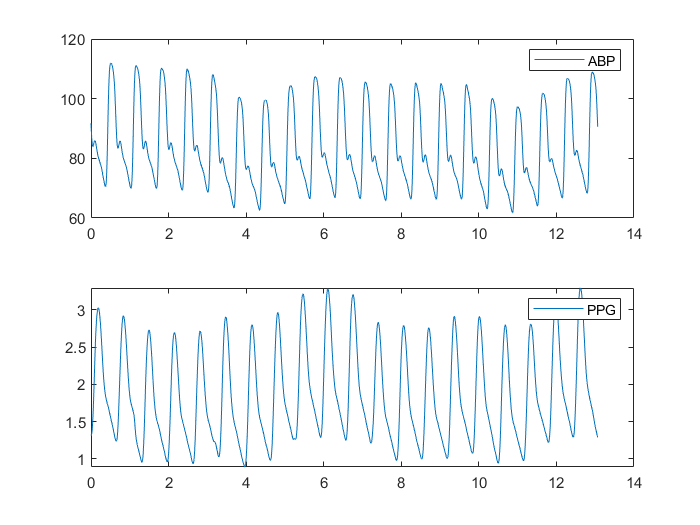

id = randi(length(segmentedData));
sample = segmentedData{id};

figure;
subplot(2,1,1)
plot(sample(:,1), sample(:,2));
legend(["ABP"])

subplot(2,1,2)
plot(sample(:,1), sample(:,3));
legend(["PPG"])